# Resolve Tones in an Unknown Signal

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the signal.

load ./data/unknownfan.mat
disp("Fan rotation: " + fr + " Hz")

Fan rotation: 66.6667 Hz


disp("Ball spin: " + frR + " Hz")

Ball spin: 211.96 Hz


disp("Inner race: " + frI  + " Hz")

Inner race: 256.87 Hz


disp("Outer race: " + frO + " Hz")

Outer race: 143.13 Hz


disp("Cage speed: " + frC + " Hz")

Cage speed: 23.85 Hz


## Task 1

If you are expecting frequency content at specific frequencies, you can perform spectral analysis based on the tones you expect to see. But what about if you're working with data that you haven't seen before?

In this project, you'll calculate the power spectrum and try to confirm if your spectrum is finding the frequencies correctly.

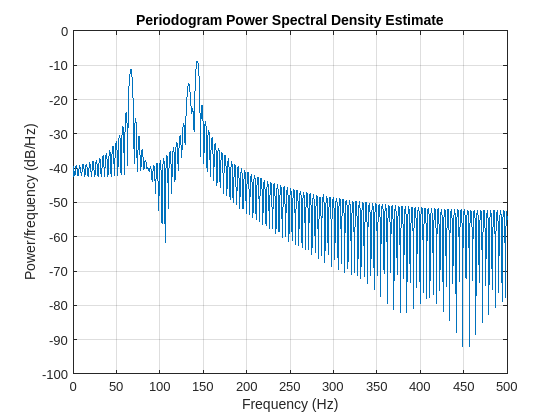

nfft = 2^12;
periodogram(sig,ones(n,1),nfft,fs);

## Task 2

There are three clear peaks in the power spectrum. To determine what fan components are associated with the peak locations, you can save the locations to a variable.

[p,f] = periodogram(sig,ones(n,1),nfft,fs);
[~,loc] = findpeaks(10*log10(p),f,"NPeaks",3,"SortStr","descend")

loc =   143.0664
   66.6504
  133.3008


## Task 3

Look at the frequency location values. What do they correspond to, and how precise are the locations?

The critical frequency values for different fan components are displayed at the top of the script. Compare them to the peak locations and use them to calculate the error. For example, `loc``(``2``)` is close to `fr`, so you can calculate the error with

`err2` `=` `abs``(``loc``(``2``)``-``fr``)`

If you're not sure about the other two locations, click **Hint** below to view the corresponding critical frequencies.

err1 = abs(loc(1)-frO)

err1 = 0.0636

err2 = abs(loc(2)-fr)

err2 = 0.0163

err3 = abs(loc(3)-2*fr)

err3 = 0.0326

## Task 4 

Since there is frequency content corresponding to the fan's outer race, the fan's outer race is broken. But have you found all the tones in the signal? If you change the window, you may discover other prominent frequencies.

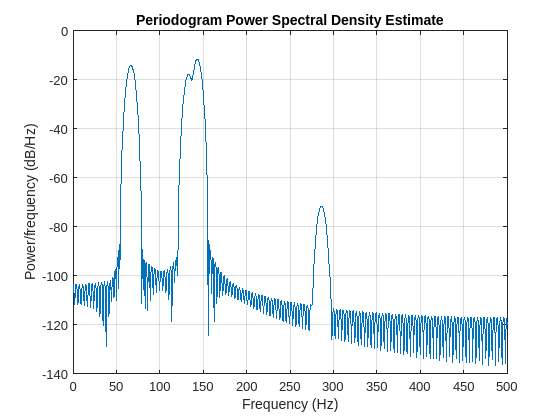

periodogram(sig,kaiser(n,10),nfft,fs);

## Task 5

Increasing the beta value decreased the height of the sidelobes, and you can now see another tone around 300 Hz.

Try out different beta values. If you increase the beta value too much, the mainlobes get so wide that 2 of the tones merge.

[p,f] = periodogram(sig,kaiser(n,10),nfft,fs);
[~,loc] = findpeaks(10*log10(p),f,"NPeaks",4,"SortStr","descend")

loc =   143.0664
   66.6504
  133.0566
  286.3770


err4 = abs(loc(4)-2*frO)

err4 = 0.1170